# File Name: Search_Registration_06_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Align Two Point Clouds Using NDT Algorithm

Load point cloud data.

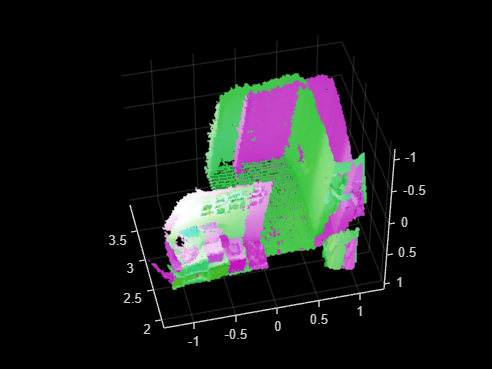

ld = load('livingRoom.mat');
moving = ld.livingRoomData{1};
fixed = ld.livingRoomData{2};

%%%%%%%%%% TODO %%%%%%%%%%
% Show the moving and fixed point clouds
pcshowpair(moving,fixed,'VerticalAxis','Y','VerticalAxisDir','Down')

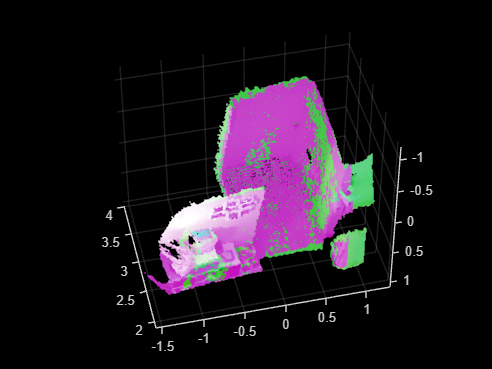


% To improve the efficiency and accuracy of the NDT registration algorithm, downsample the moving point cloud.
movingDownsampled = pcdownsample(moving,'gridAverage',0.1);

% Voxelize the point cloud into cubes of sidelength 0.5. Apply the rigid registration using the NDT algorithm.
gridStep = 0.5;

%%%%%%%%%% TODO %%%%%%%%%%
tform = pcregisterndt(movingDownsampled,fixed,gridStep);

% Visualize the alignment.
movingReg = pctransform(moving,tform);
pcshowpair(movingReg,fixed,'VerticalAxis','Y','VerticalAxisDir','Down')